clc
clear all
close all

## global variables

global q0 ref dref b tc K SATURATION tc tfin USE_PREDICTION PREDICTION_HORIZON PREDICTION_SATURATION_TOLERANCE;

## variables

TRAJECTORY = 6

TRAJECTORY = 6

INITIAL_CONDITIONS = 1

INITIAL_CONDITIONS = 1

USE_PREDICTION = false

USE_PREDICTION = logical
   0


PREDICTION_HORIZON = 5

PREDICTION_HORIZON = 5

% distance from the center of the unicycle to the point being tracked
% ATTENZIONE! CI SARA' SEMPRE UN ERRORE COSTANTE DOVUTO A b. Minore b,
% minore l'errore
b = 0.2

b = 0.2000

% proportional gain
K = eye(2)*2

K =      2     0
     0     2



tc = 0.05

tc = 0.0200

tfin=10

tfin = 10


% saturation
% HYP: a diff. drive robot with motors spinning at 100rpm -> 15.7 rad/s.
% Radius of wheels 10cm. Wheels distanced 15cm from each other
% applying transformation, v
% saturation = [1.57, 20];
SATURATION = [1; 1];
PREDICTION_SATURATION_TOLERANCE = 0.0;

## launch simulation

initial state In order, [x, y, theta]

q0 = set_initial_conditions(INITIAL_CONDITIONS)

q0 =          0
         0
    3.1416


% trajectory to track
[ref, dref] = set_trajectory(TRAJECTORY)

$$ref = \left(\begin{array}{c} \frac{2\,s}{5}\\ \cos\left(\frac{2\,s}{5}\right) \end{array}\right)$$

$$dref = \left(\begin{array}{c} \frac{2}{5}\\ -\frac{2\,\sin\left(\frac{2\,s}{5}\right)}{5} \end{array}\right)$$


global tu uu


figure(1)
PREDICTION_HORIZON = 0;
[t, q, ref_t, U] = simulate_discr(tfin);
plot_results(t, q, ref_t, U);

figure(2)
PREDICTION_HORIZON = 1;
[t1, q1, ref_t1, U1] = simulate_discr(tfin);
plot_results(t1, q1, ref_t1, U1);


figure(3)
PREDICTION_HORIZON = 40;
[t2, q2, ref_t2, U2] = simulate_discr(tfin);

steps = 500

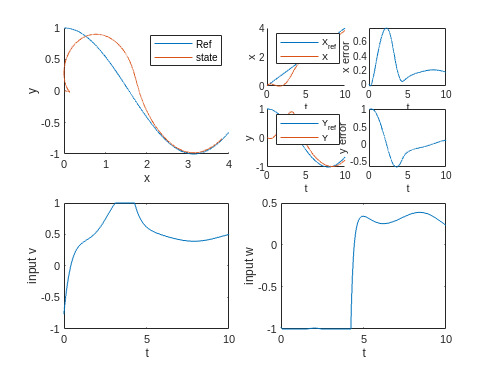

plot_results(t2, q2, ref_t2, U2);

%figure(3)

steps = 500

%subplot(1, 2, 1)
%plot(tu, uu(1, 
%subplot(1, 2, 2)
%plot(tu, uu(2, :))
%plot_results(t, x-x1, ref_t-ref_t1, U-U1);

## FUNCTION DECLARATIONS

% Discrete-time simulation
function [t, q, ref_t, U] = simulate_discr(tfin)
    global ref q0 u_discr tc

    steps = tfin/tc
    
    q = q0';
    t = 0;
    u_discr = control_act(t, q0);
    U = u_discr';
    
    for n = 1:steps
        tspan = [(n-1)*tc n*tc];
        z0 = q(end, :);
        
        [v, z] = ode45(@sistema, tspan, z0);

        q = [q; z];
        t = [t; v];
        
        u_discr = control_act(t(end), q(end, :));
        U = [U; ones(length(v), 1)*u_discr'];
    end

    ref_t = double(subs(ref, t'))';
end


% Continuos-time simulation
function [t, q, ref, U] = simulate_cont(tfin)
    global ref q0

    % simulation time
    tspan = linspace(0, tfin);
    % execute simulation
    [t, q] = ode45(@sistema, tspan, q0);
    
    % recalc and save input at each timestep
    ts = size(t);
    rows = ts(1);
    U = zeros(rows, 2);
    for row = 1:rows
        U(row, :) = control_act(t(row), q(row, :));
    end
    
    % plot results
    ref = double(subs(ref, t'))';
end

% Plots
function plot_results(t, x, ref, U)
    subplot(2,2,1)
    hold on
    plot(ref(:, 1), ref(:, 2), "DisplayName", "Ref")
    plot(x(:, 1), x(:, 2), "DisplayName", "state")
    xlabel('x')
    ylabel('y')
    legend()
    subplot(2,2,3)
    plot(t, U(:, 1))
    xlabel('t')
    ylabel('input v')
    subplot(2,2,4)
    plot(t, U(:, 2))
    xlabel('t')
    ylabel('input w')
    
    
    subplot(4,4,3)
    hold on
    xlabel('t')
    ylabel('x')
    plot(t, ref(:, 1), "DisplayName", "X_{ref}");
    plot(t, x(:, 1), "DisplayName", "X");
    legend()
    hold off
    
    subplot(4,4,4)
    plot(t, ref(:, 1) - x(:, 1));
    xlabel('t')
    ylabel('x error')
    
    subplot(4,4,7)
    hold on
    xlabel('t')
    ylabel('y')
    plot(t, ref(:, 2), "DisplayName", "Y_{ref}");
    plot(t, x(:, 2), "DisplayName", "Y");
    legend()
    hold off
    
    subplot(4,4,8)
    plot(t, ref(:, 2) - x(:, 2));
    xlabel('t')
    ylabel('y error')
end